# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');
warning('off','all')

Since we deal with a discrete-time implementation of controllers, we need to specify the sampling time. For this reason we select a choice of T on wich we are going to test our controllers.

T = [0.001 0.01 0.05];

## 2.1 Design by emulation

The discretization problem consists of finding a discrete-time controller C(z) such that the input–output transfer function of the sampled–data controller, approximates (in some sense) the transfer function C0(s).

### **2.1.1 Position PID Controller**

Discrete PID design

% Config
simul.Ts_selector = 2;
simul.disc_select = 2; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
simul.stepdeg = 360;
simul.FFW = 1;

pidz.Kw = 0; % Handout: 5/perf.ts5, Challange Lab1: 13.33

% Define transfer function
s = tf('s');
Ts = T(simul.Ts_selector);
z = tf('z',Ts);
Pdelay = exp(-s*Ts/2)*(paramP.km/(gbox.N*s*(paramP.Tm*s+1)));

% Get magnitue and phase at the desired frequency
[magPwg, phasePwg] = bode(Pdelay, perf.wg);
dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

% Estimation of the paramters of the PID-discrete time controller (system with time delay)
a = 4000; % TUNE                     % First attempt 4000
pidz.K = dK * cos(dPh);

Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*perf.wg);
Ti = a*Td;
pidz.T_l = 1/(2*perf.wg);

pidz.Kd = pidz.K*Td;
pidz.Ki = pidz.K/Ti;

s_forward = (z-1)/Ts;
s_backward = (z-1)/(Ts*z);

pidz.C = pidz.K + pidz.Ki*(1/s) + pidz.Kd * (s/(pidz.T_l*s + 1)); % CT model

pidz.Cb = pidz.K + pidz.Ki*(1/s_backward) + pidz.Kd * (s_backward/(pidz.T_l*s_backward + 1)); % backward disc
pidz.Cf = pidz.K + pidz.Ki*(1/s_forward) + pidz.Kd * (s_forward/(pidz.T_l*s_forward + 1)); % forward disc
pidz.Ctust = c2d(pidz.C,Ts,'tustin'); % tustin disc
pidz.Czoh = c2d(pidz.C,Ts,'zoh'); % 'exact' disc

pidz.controllers = [pidz.Cf, pidz.Cb, pidz.Ctust, pidz.Czoh];

% Get data of implemented controller
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');

Simulation for 1ms (all the si)

%%% Design controllers using different discretization for Ts = 10ms

simul.Ts_selector = 1;
Ts = T(simul.Ts_selector);
z = tf('z',Ts);
Pdelay = exp(-s*Ts/2)*(paramP.km/(gbox.N*s*(paramP.Tm*s+1)));

% Get magnitue and phase at the desired frequency
[magPwg, phasePwg] = bode(Pdelay, perf.wg);
dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

% Estimation of the paramters of the PID-discrete time controller (system with time delay)
a = 4000; 
pidz.K = dK * cos(dPh);

Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*perf.wg);
Ti = a*Td;
pidz.T_l = 1/(2*perf.wg);

pidz.Kd = pidz.K*Td;
pidz.Ki = pidz.K/Ti;

s_forward = (z-1)/Ts;
s_backward = (z-1)/(Ts*z);

pidz.C = pidz.K + pidz.Ki*(1/s) + pidz.Kd * (s/(pidz.T_l*s + 1)); % CT model

pidz.Cb = pidz.K + pidz.Ki*(1/s_backward) + pidz.Kd * (s_backward/(pidz.T_l*s_backward + 1)); % backward disc
pidz.Cf = pidz.K + pidz.Ki*(1/s_forward) + pidz.Kd * (s_forward/(pidz.T_l*s_forward + 1)); % forward disc
pidz.Ctust = c2d(pidz.C,Ts,'tustin'); % tustin disc
pidz.Czoh = c2d(pidz.C,Ts,'zoh'); % 'exact' disc

% Transfer functions of controllers for different discretizations used in
% PID-emulation.
pidz.controllers = [pidz.Cf, pidz.Cb, pidz.Ctust, pidz.Czoh];

Forward Euler

simul.disc_select = 1; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.FE.T1 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Backward Euler

simul.disc_select = 2; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.BE.T1 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Tustin 

simul.disc_select = 3; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.TU.T1 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Exact

simul.disc_select = 4; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.ZOH.T1 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

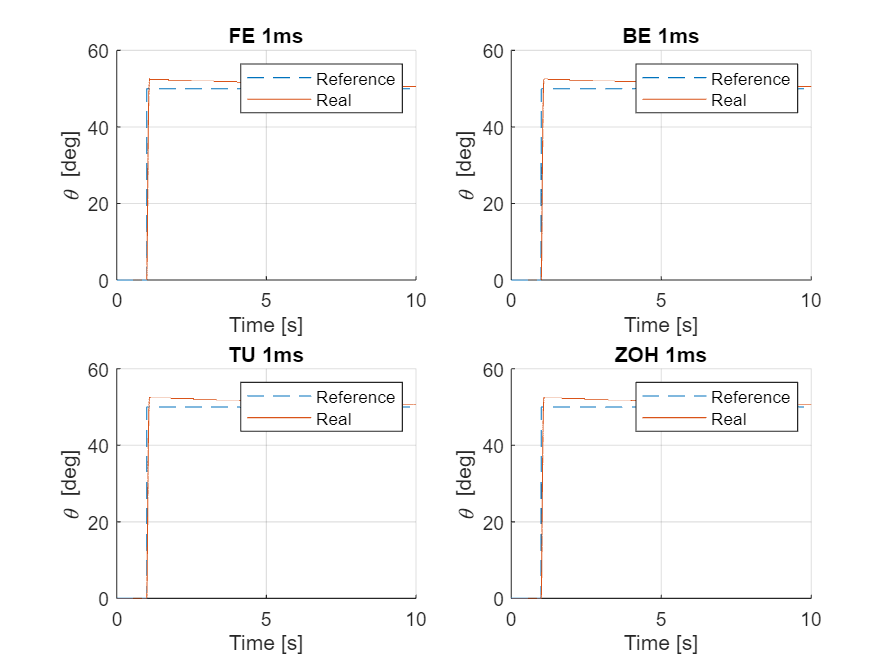

figure
subplot(2,2,1);
hold on;
plot(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--');
plot(nominal_track.FE.T1.thl_meas.time, nominal_track.FE.T1.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('FE 1ms')

subplot(2,2,2);
hold on;
plot(nominal_track.BE.T1.thref.time, nominal_track.BE.T1.thref.signals.values,'--');
plot(nominal_track.BE.T1.thl_meas.time, nominal_track.BE.T1.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('BE 1ms')

subplot(2,2,3);
hold on;
plot(nominal_track.TU.T1.thref.time, nominal_track.TU.T1.thref.signals.values,'--');
plot(nominal_track.TU.T1.thl_meas.time, nominal_track.TU.T1.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('TU 1ms')

subplot(2,2,4)
hold on;
plot(nominal_track.ZOH.T1.thref.time, nominal_track.ZOH.T1.thref.signals.values,'--');
plot(nominal_track.ZOH.T1.thl_meas.time, nominal_track.ZOH.T1.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('ZOH 1ms')

Simulation for 10ms (all the sim)

%%% Design controllers using different discretization for Ts = 10ms

simul.Ts_selector = 2;
Ts = T(simul.Ts_selector);
z = tf('z',Ts);
Pdelay = exp(-s*Ts/2)*(paramP.km/(gbox.N*s*(paramP.Tm*s+1)));

% Get magnitue and phase at the desired frequency
[magPwg, phasePwg] = bode(Pdelay, perf.wg);
dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

% Estimation of the paramters of the PID-discrete time controller (system with time delay)
a = 4000; 
pidz.K = dK * cos(dPh);

Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*perf.wg);
Ti = a*Td;
pidz.T_l = 1/(2*perf.wg);

pidz.Kd = pidz.K*Td;
pidz.Ki = pidz.K/Ti;

s_forward = (z-1)/Ts;
s_backward = (z-1)/(Ts*z);

pidz.C = pidz.K + pidz.Ki*(1/s) + pidz.Kd * (s/(pidz.T_l*s + 1)); % CT model

pidz.Cb = pidz.K + pidz.Ki*(1/s_backward) + pidz.Kd * (s_backward/(pidz.T_l*s_backward + 1)); % backward disc
pidz.Cf = pidz.K + pidz.Ki*(1/s_forward) + pidz.Kd * (s_forward/(pidz.T_l*s_forward + 1)); % forward disc
pidz.Ctust = c2d(pidz.C,Ts,'tustin'); % tustin disc
pidz.Czoh = c2d(pidz.C,Ts,'zoh'); % 'exact' disc

% Transfer functions of controllers for different discretizations used in
% PID-emulation.
pidz.controllers = [pidz.Cf, pidz.Cb, pidz.Ctust, pidz.Czoh];

Forward Euler

simul.disc_select = 1; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.FE.T2 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Backward Euler

simul.disc_select = 2; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.BE.T2 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Tustin 

simul.disc_select = 3; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.TU.T2 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Exact

simul.disc_select = 4; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.ZOH.T2 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

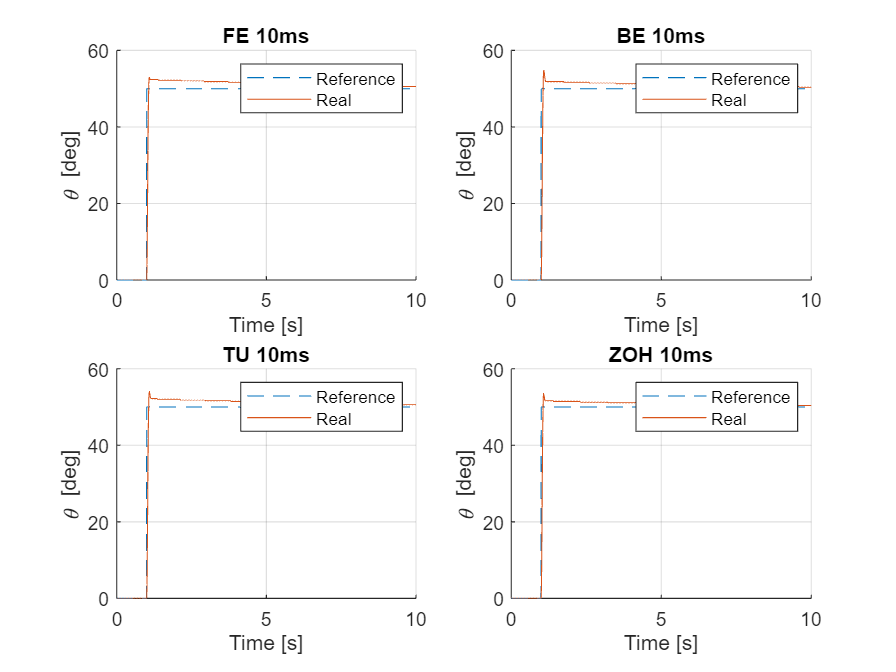

figure
subplot(2,2,1);
hold on;
plot(nominal_track.FE.T2.thref.time, nominal_track.FE.T2.thref.signals.values,'--');
plot(nominal_track.FE.T2.thl_meas.time, nominal_track.FE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('FE 10ms')

subplot(2,2,2);
hold on;
plot(nominal_track.BE.T2.thref.time, nominal_track.BE.T2.thref.signals.values,'--');
plot(nominal_track.BE.T2.thl_meas.time, nominal_track.BE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('BE 10ms')

subplot(2,2,3);
hold on;
plot(nominal_track.TU.T2.thref.time, nominal_track.TU.T2.thref.signals.values,'--');
plot(nominal_track.TU.T2.thl_meas.time, nominal_track.TU.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('TU 10ms')

subplot(2,2,4)
hold on;
plot(nominal_track.ZOH.T2.thref.time, nominal_track.ZOH.T2.thref.signals.values,'--');
plot(nominal_track.ZOH.T2.thl_meas.time, nominal_track.ZOH.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('ZOH 10ms')

Simulation for 50 ms (all the sim)

%%% Design controllers using different discretization for Ts = 10ms

simul.Ts_selector = 3;
Ts = T(simul.Ts_selector);
z = tf('z',Ts);
Pdelay = exp(-s*Ts/2)*(paramP.km/(gbox.N*s*(paramP.Tm*s+1)));

% Get magnitue and phase at the desired frequency
[magPwg, phasePwg] = bode(Pdelay, perf.wg);
dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

% Estimation of the paramters of the PID-discrete time controller (system with time delay)
a = 4000; 
pidz.K = dK * cos(dPh);

Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*perf.wg);
Ti = a*Td;
pidz.T_l = 1/(2*perf.wg);

pidz.Kd = pidz.K*Td;
pidz.Ki = pidz.K/Ti;

s_forward = (z-1)/Ts;
s_backward = (z-1)/(Ts*z);

pidz.C = pidz.K + pidz.Ki*(1/s) + pidz.Kd * (s/(pidz.T_l*s + 1)); % CT model

pidz.Cb = pidz.K + pidz.Ki*(1/s_backward) + pidz.Kd * (s_backward/(pidz.T_l*s_backward + 1)); % backward disc
pidz.Cf = pidz.K + pidz.Ki*(1/s_forward) + pidz.Kd * (s_forward/(pidz.T_l*s_forward + 1)); % forward disc
pidz.Ctust = c2d(pidz.C,Ts,'tustin'); % tustin disc
pidz.Czoh = c2d(pidz.C,Ts,'zoh'); % 'exact' disc

% Transfer functions of controllers for different discretizations used in
% PID-emulation.
pidz.controllers = [pidz.Cf, pidz.Cb, pidz.Ctust, pidz.Czoh];

Forward Euler

simul.disc_select = 1; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.FE.T3 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Backward Euler

simul.disc_select = 2; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.BE.T3 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Tustin 

simul.disc_select = 3; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.TU.T3 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Exact

simul.disc_select = 4; % {1: forward, 2: backward, 3: tustin, 4: exact/zoh}
[pidz.Cnum, pidz.Cdenom] = tfdata(pidz.controllers(simul.disc_select), 'v');
nominal_track.ZOH.T3 = sim('PID_emulation','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

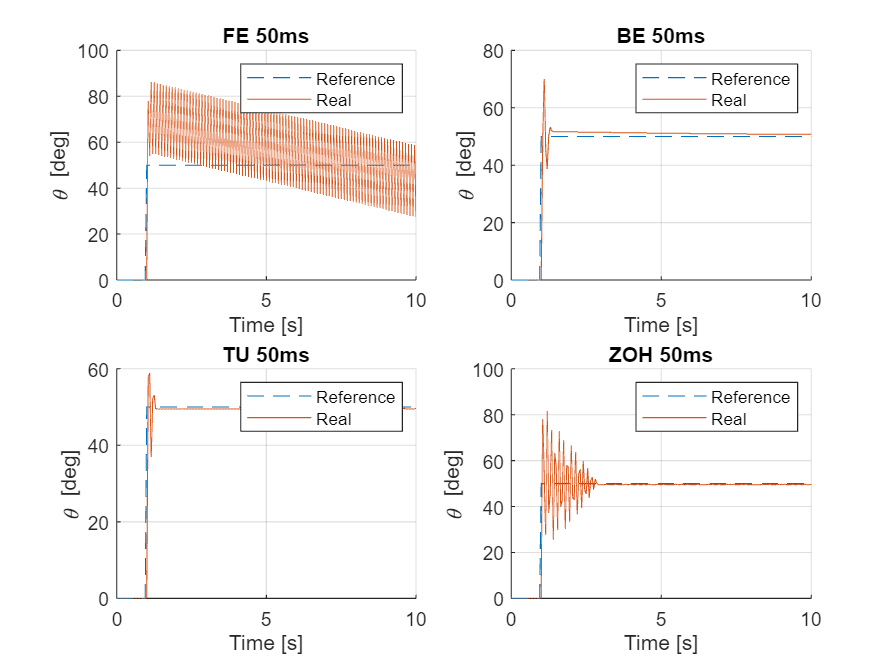

figure
subplot(2,2,1);
hold on;
plot(nominal_track.FE.T3.thref.time, nominal_track.FE.T3.thref.signals.values,'--');
plot(nominal_track.FE.T3.thl_meas.time, nominal_track.FE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('FE 50ms')

subplot(2,2,2);
hold on;
plot(nominal_track.BE.T3.thref.time, nominal_track.BE.T3.thref.signals.values,'--');
plot(nominal_track.BE.T3.thl_meas.time, nominal_track.BE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('BE 50ms')

subplot(2,2,3);
hold on;
plot(nominal_track.TU.T3.thref.time, nominal_track.TU.T3.thref.signals.values,'--');
plot(nominal_track.TU.T3.thl_meas.time, nominal_track.TU.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('TU 50ms')

subplot(2,2,4)
hold on;
plot(nominal_track.ZOH.T3.thref.time, nominal_track.ZOH.T3.thref.signals.values,'--');
plot(nominal_track.ZOH.T3.thl_meas.time, nominal_track.ZOH.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('ZOH 50ms')

#### **Antiwindup Method**

Sampling Time is 10ms 

%%% Test Anti-Windup for BE Method

% Correct model to use is PID_emulation_be_awu which explicitly implements
% BE discretization of PID. Its only necessary to set the correct gains.
simul.stepdeg = 360;
simul.Ts_selector = 2;
Ts = T(simul.Ts_selector);

Pdelay = exp(-s*Ts/2)*(paramP.km/(gbox.N*s*(paramP.Tm*s+1)));

% Get magnitue and phase at the desired frequency
[magPwg, phasePwg] = bode(Pdelay, perf.wg);
dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

% Controller gains for discrete PID implemented in the model
a = 4000; 
pidz.K = dK * cos(dPh);

Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*perf.wg);
Ti = a*Td;
pidz.T_l = 1/(2*perf.wg);

pidz.Kd = pidz.K*Td;
pidz.Ki = pidz.K/Ti;

With Anti-Windup

% Kw is awu Gain

pidz.Kw = 5/perf.ts5;    % Handout: 5/perf.ts5, Challange Lab1: 13.33    % TUNE
nominal_track.AWU.BE = sim('PID_emulation_be_awu.slx','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Without Anti-Windup

pidz.Kw = 0;
nominal_track.NOAWU.BE = sim('PID_emulation_be_awu.slx','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

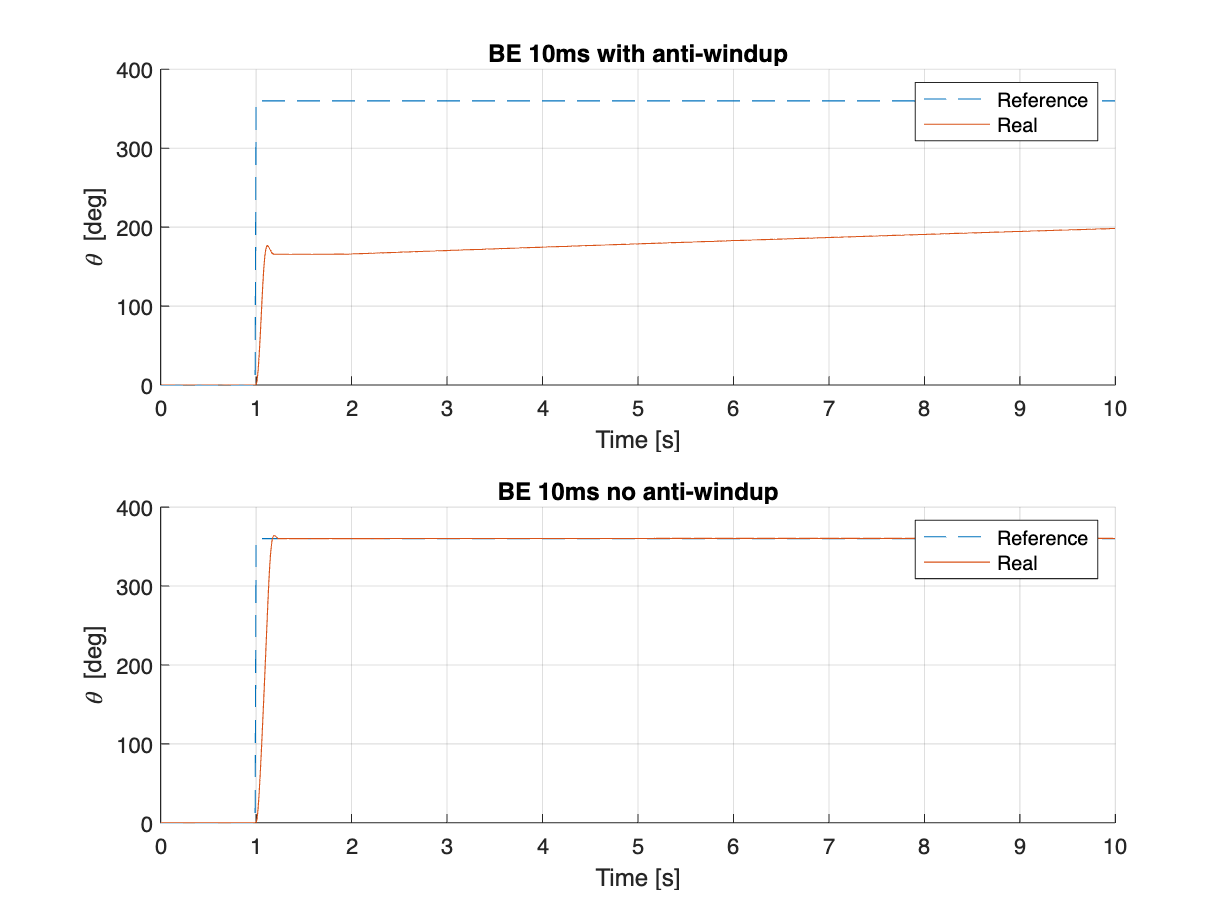

figure
subplot(2,1,1)
hold on;
plot(nominal_track.AWU.BE.thref.time, nominal_track.AWU.BE.thref.signals.values,'--');
plot(nominal_track.AWU.BE.thl_meas.time, nominal_track.AWU.BE.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('BE 10ms with anti-windup')
subplot(2,1,2)
hold on;
plot(nominal_track.NOAWU.BE.thref.time, nominal_track.NOAWU.BE.thref.signals.values,'--');
plot(nominal_track.NOAWU.BE.thl_meas.time, nominal_track.NOAWU.BE.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('BE 10ms no anti-windup')

#### Feedforward Method

% Gains inherited from last block (10ms + BE discretization)
simul.FFW = 1; % enable ffw
pidz.Kw = 0;   % make sure we dont have awu
nominal_track.FFW.BE = sim('PID_emulation_be_ff.slx','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

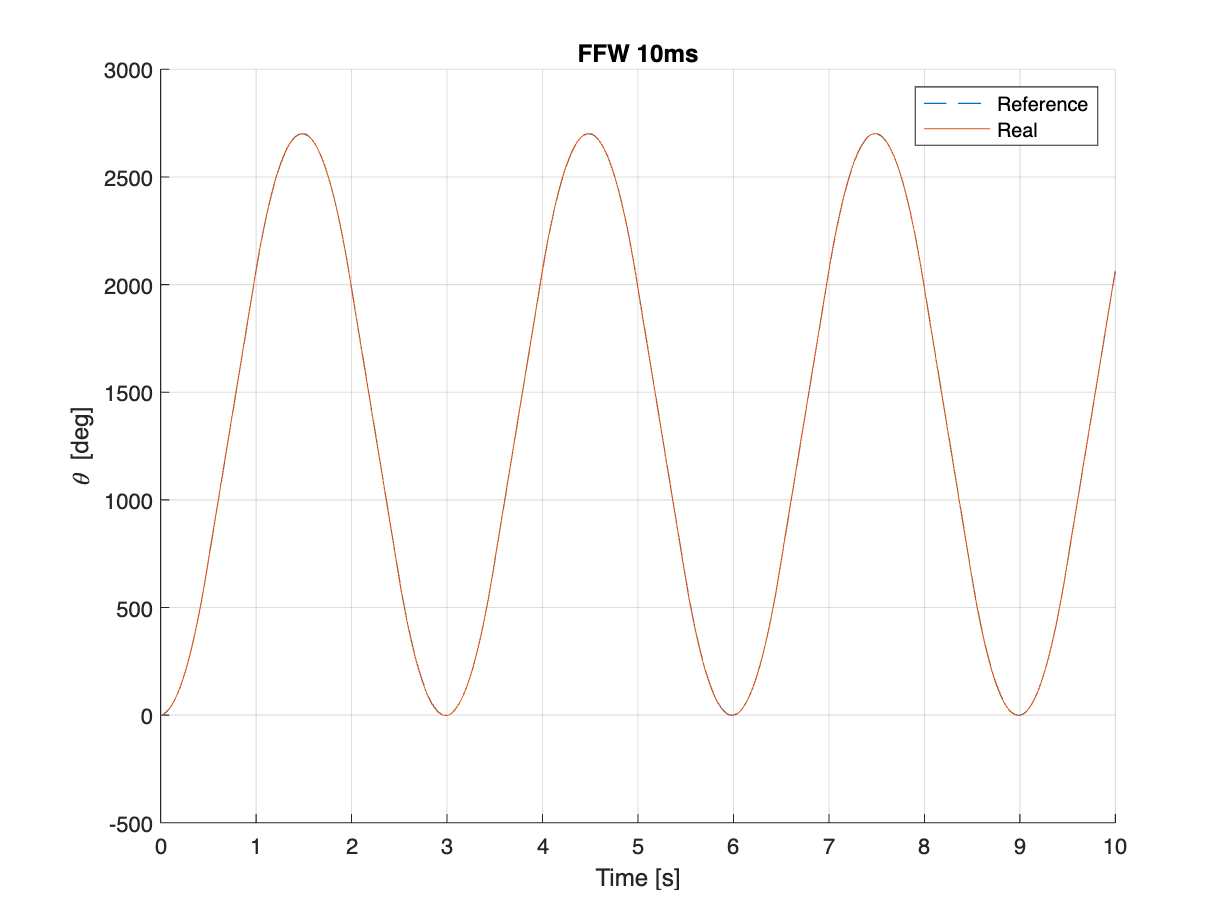

figure
hold on;
plot(nominal_track.FFW.BE.thref.time, nominal_track.FFW.BE.thref.signals.values,'--');
plot(nominal_track.FFW.BE.thl_meas.time, nominal_track.FFW.BE.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('FFW 10ms')

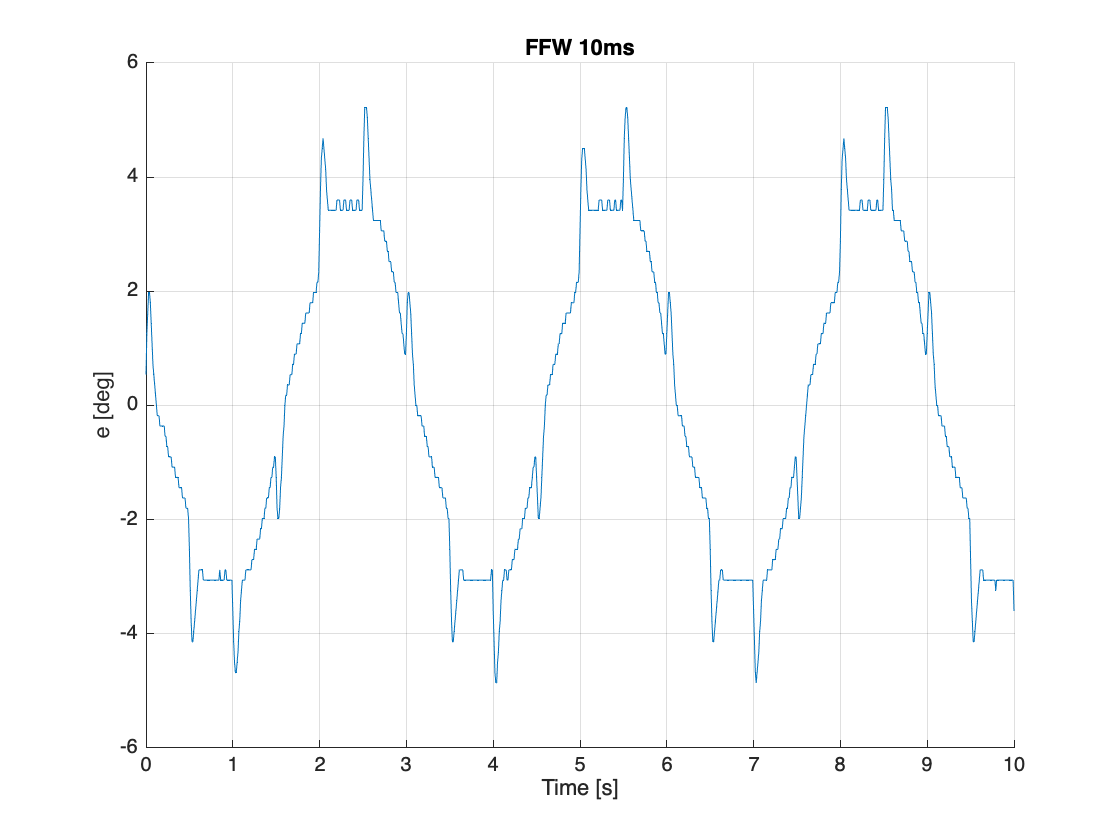

figure
hold on;
plot(nominal_track.FFW.BE.e.time, nominal_track.FFW.BE.e.signals.values);
grid on;
xlabel('Time [s]')
ylabel('e [deg]')
title('FFW 10ms')

### **2.1.2 Position State-Space Controller**

Reconsider the position state–space controller for nominal and robust perfect tracking of constant set–points designed in the second laboratory activity. Differently from the second laboratory activity, suppose that the plant state is not fully accessible, so that a state observer is required to get an estimate of all the unmeasurable state variables.

**Reduced order state observer (CT)**

redObs.L = 4/paramP.Tm;                     % Obs Gain
redObs.A0 = -(1/paramP.Tm + redObs.L);      % Manually placing EV to -5/paramP.Tm
redObs.B0 = [paramP.km/(gbox.N*paramP.Tm), -(1/paramP.Tm + redObs.L)*redObs.L];
redObs.C0 = [0; 1];
redObs.D0 = [0 1; 0 redObs.L];

**CT Test - Nominal tracking**

simul.stepdeg = 40;
nominal_track.CT.deg_40 = sim('ss_nominal_estimator_CT','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
simul.stepdeg = 70;
nominal_track.CT.deg_70 = sim('ss_nominal_estimator_CT','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
simul.stepdeg = 120;
nominal_track.CT.deg_120 = sim('ss_nominal_estimator_CT','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

In this figure we check the tracking of the reference and the difference between the real and the estimated speed

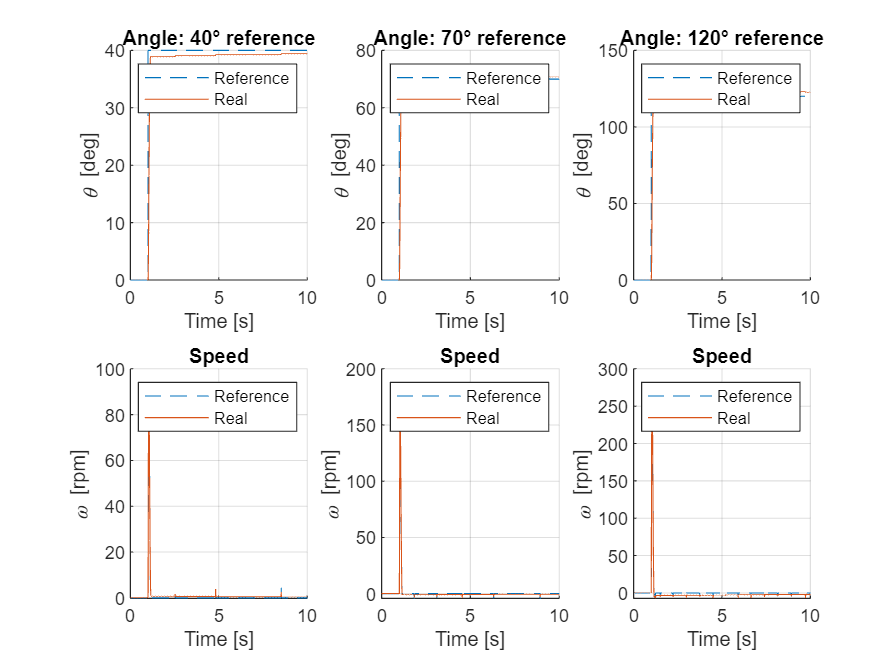

figure
subplot(2,3,1);
hold on;
plot(nominal_track.CT.deg_40.thref.time, nominal_track.CT.deg_40.thref.signals.values,'--');
plot(nominal_track.CT.deg_40.thl_meas.time, nominal_track.CT.deg_40.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(nominal_track.CT.deg_70.thref.time, nominal_track.CT.deg_70.thref.signals.values,'--');
plot(nominal_track.CT.deg_70.thl_meas.time, nominal_track.CT.deg_70.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(nominal_track.CT.deg_120.thref.time, nominal_track.CT.deg_120.thref.signals.values,'--');
plot(nominal_track.CT.deg_120.thl_meas.time, nominal_track.CT.deg_120.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')
subplot(2,3,4)
hold on;
plot(nominal_track.CT.deg_40.wl_meas.time, nominal_track.CT.deg_40.wl_meas.signals.values,'--');
plot(nominal_track.CT.deg_40.wl_est.time, nominal_track.CT.deg_40.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(nominal_track.CT.deg_70.wl_meas.time, nominal_track.CT.deg_70.wl_meas.signals.values,'--');
plot(nominal_track.CT.deg_70.wl_est.time, nominal_track.CT.deg_70.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(nominal_track.CT.deg_120.wl_meas.time, nominal_track.CT.deg_120.wl_meas.signals.values,'--');
plot(nominal_track.CT.deg_120.wl_est.time, nominal_track.CT.deg_120.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

**Forwar Euler discretization**

We can repeat the same procedure also for other discretization methods. Pay attention to the simulation time T!! We perform the test of the controller using different sampling times

simul.stepdeg = 50;
simul.Ts_selector = 1;

Simulation for 1 ms

redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

nominal_track.FE.T1 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','8','AlgebraicLoopMsg', 'off');

Simulation for 10 ms

simul.Ts_selector = 2;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

nominal_track.FE.T2 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','8','AlgebraicLoopMsg', 'off');

Simulation for 50 ms

simul.Ts_selector = 3;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

nominal_track.FE.T3 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','8','AlgebraicLoopMsg', 'off');

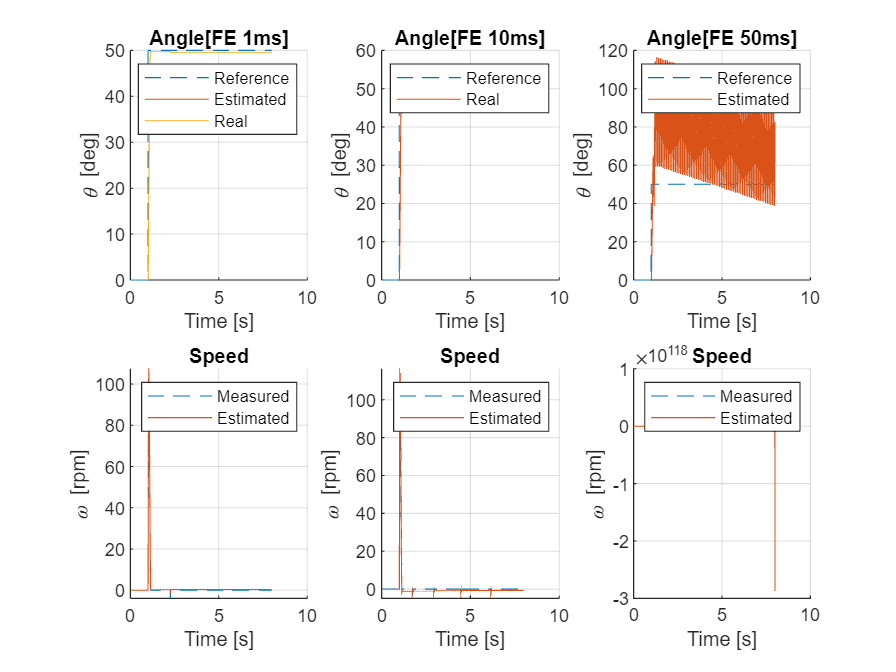

figure
subplot(2,3,1);
hold on;
plot(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--');
plot(nominal_track.FE.T1.thl_est.time, nominal_track.FE.T1.thl_meas.signals.values);
plot(nominal_track.FE.T1.thl_meas.time, nominal_track.FE.T1.thl_meas.signals.values);
legend('Reference', 'Estimated', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle[FE 1ms]')

subplot(2,3,2);
hold on;
plot(nominal_track.FE.T2.thref.time, nominal_track.FE.T2.thref.signals.values,'--');
plot(nominal_track.FE.T2.thl_est.time, nominal_track.FE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle[FE 10ms]')

subplot(2,3,3);
hold on;
plot(nominal_track.FE.T3.thref.time, nominal_track.FE.T3.thref.signals.values,'--');
plot(nominal_track.FE.T3.thl_est.time, nominal_track.FE.T3.thl_meas.signals.values);
legend('Reference', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle[FE 50ms]')
subplot(2,3,4)
hold on;
plot(nominal_track.FE.T1.wl_meas.time, nominal_track.FE.T1.wl_meas.signals.values,'--');
plot(nominal_track.FE.T1.wl_est.time, nominal_track.FE.T1.wl_est.signals.values);
legend('Measured', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(nominal_track.FE.T2.wl_meas.time, nominal_track.FE.T2.wl_meas.signals.values,'--');
plot(nominal_track.FE.T2.wl_est.time, nominal_track.FE.T2.wl_est.signals.values);
legend('Measured', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(nominal_track.FE.T3.wl_meas.time, nominal_track.FE.T3.wl_meas.signals.values,'--');
plot(nominal_track.FE.T3.wl_est.time, nominal_track.FE.T3.wl_est.signals.values);
legend('Measured', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

**Backward Euler discretization**

simul.stepdeg = 50;

Simulation for 1 ms

simul.Ts_selector = 1;
redObs.Ph0 = inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.Gamma0 = (1 - redObs.A0*T(simul.Ts_selector))\redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0/(1 - redObs.A0*T(simul.Ts_selector));
redObs.J0 = redObs.D0 + redObs.C0/(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);
disp(redObs.J0)

         0    1.0000
    0.1360  107.8530




nominal_track.BE.T1 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Simulation for 10 ms

simul.Ts_selector = 2;
redObs.Ph0 = inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.Gamma0 = (1 - redObs.A0*T(simul.Ts_selector))\redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0/(1 - redObs.A0*T(simul.Ts_selector));
redObs.J0 = redObs.D0 + redObs.C0/(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);
disp(redObs.J0)

         0    1.0000
    0.6145   48.7285




nominal_track.BE.T2 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Simulation for 50 ms

simul.Ts_selector = 3;
redObs.Ph0 = inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.Gamma0 = (1 - redObs.A0*T(simul.Ts_selector))\redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0/(1 - redObs.A0*T(simul.Ts_selector));
redObs.J0 = redObs.D0 + redObs.C0/(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);
disp(redObs.J0)

         0    1.0000
    0.8941   14.1800




nominal_track.BE.T3 = sim('ss_nominal_estimator_DT','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

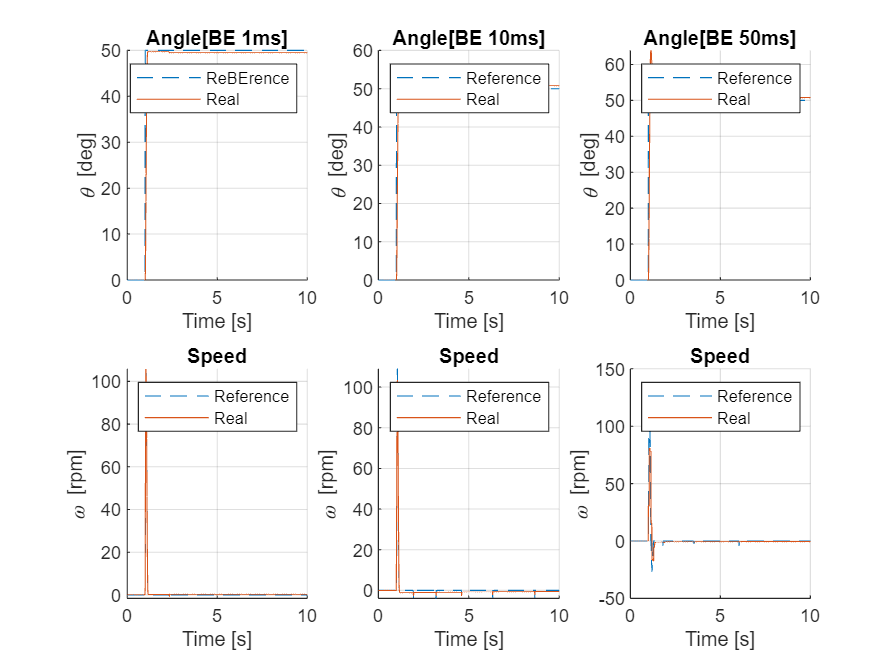

figure
subplot(2,3,1);
hold on;
plot(nominal_track.BE.T1.thref.time, nominal_track.BE.T1.thref.signals.values,'--');
plot(nominal_track.BE.T1.thl_meas.time, nominal_track.BE.T1.thl_meas.signals.values);
legend('ReBErence', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle[BE 1ms]')

subplot(2,3,2);
hold on;
plot(nominal_track.BE.T2.thref.time, nominal_track.BE.T2.thref.signals.values,'--');
plot(nominal_track.BE.T2.thl_meas.time, nominal_track.BE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle[BE 10ms]')

subplot(2,3,3);
hold on;
plot(nominal_track.BE.T3.thref.time, nominal_track.BE.T3.thref.signals.values,'--');
plot(nominal_track.BE.T3.thl_meas.time, nominal_track.BE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle[BE 50ms]')
subplot(2,3,4)
hold on;
plot(nominal_track.BE.T1.wl_meas.time, nominal_track.BE.T1.wl_meas.signals.values,'--');
plot(nominal_track.BE.T1.wl_est.time, nominal_track.BE.T1.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(nominal_track.BE.T2.wl_meas.time, nominal_track.BE.T2.wl_meas.signals.values,'--');
plot(nominal_track.BE.T2.wl_est.time, nominal_track.BE.T2.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(nominal_track.BE.T3.wl_meas.time, nominal_track.BE.T3.wl_meas.signals.values,'--');
plot(nominal_track.BE.T3.wl_est.time, nominal_track.BE.T3.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

save('NominalTrack.mat','nominal_track');

Reduced order state observer (CT) for** robust traking**

If we select a smaller value fot L, then we can guarantee the stability also for the second sampling time in forward Euler. This happne becuase we are acting on pole mapping.

% redObs.L = 5/paramP.Tm;
redObs.L = 4/paramP.Tm; 

redObs.A0 = -(1/paramP.Tm + redObs.L);
redObs.B0 = [paramP.km/(gbox.N*paramP.Tm), -(1/paramP.Tm + redObs.L)*redObs.L];
redObs.C0 = [0; 1];
redObs.D0 = [0 1; 0 redObs.L];

**CT - Robust tracking**

We have already implemeted the observer. we have just to put in the model and to test it

simul.stepdeg = 40;
robust_track.CT.deg_40 = sim('ss_robust_estimator_CT','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
simul.stepdeg = 70;
robust_track.CT.deg_70 = sim('ss_robust_estimator_CT','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
simul.stepdeg = 120;
robust_track.CT.deg_120 = sim('ss_robust_estimator_CT','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Not all the controllers we used K4 poles.

In this figure we check the tracking of the reference and the difference between the real and the estimated speed

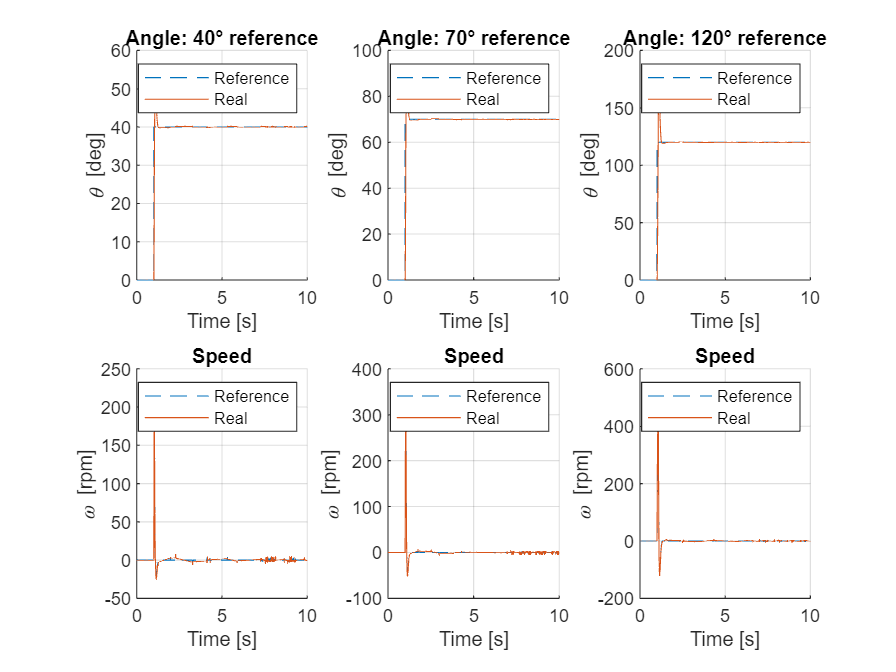

figure
subplot(2,3,1);
hold on;
plot(robust_track.CT.deg_40.thref.time, robust_track.CT.deg_40.thref.signals.values,'--');
plot(robust_track.CT.deg_40.thl_meas.time, robust_track.CT.deg_40.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 40° reference')

subplot(2,3,2);
hold on;
plot(robust_track.CT.deg_70.thref.time, robust_track.CT.deg_70.thref.signals.values,'--');
plot(robust_track.CT.deg_70.thl_meas.time, robust_track.CT.deg_70.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 70° reference')

subplot(2,3,3);
hold on;
plot(robust_track.CT.deg_120.thref.time, robust_track.CT.deg_120.thref.signals.values,'--');
plot(robust_track.CT.deg_120.thl_meas.time, robust_track.CT.deg_120.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle: 120° reference')

subplot(2,3,4)
hold on;
plot(robust_track.CT.deg_40.wl_meas.time, robust_track.CT.deg_40.wl_meas.signals.values,'--');
plot(robust_track.CT.deg_40.wl_est.time, robust_track.CT.deg_40.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

subplot(2,3,5)
hold on;
plot(robust_track.CT.deg_70.wl_meas.time, robust_track.CT.deg_70.wl_meas.signals.values,'--');
plot(robust_track.CT.deg_70.wl_est.time, robust_track.CT.deg_70.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

subplot(2,3,6)
hold on;
plot(robust_track.CT.deg_120.wl_meas.time, robust_track.CT.deg_120.wl_meas.signals.values,'--');
plot(robust_track.CT.deg_120.wl_est.time, robust_track.CT.deg_120.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

**Forward Euler discretization**

At each simulation we choice a different simulation time. This tije must be set in the discrete integrator, in all the 'zoh' blocks.

simul.stepdeg = 50;

Simulation for 1 ms

simul.Ts_selector = 1;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
display(redObs.Ph0)

    0.8442



redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;
display(redObs.J0)

         0    1.0000
         0  124.6591




robust_track.FE.T1 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Simulation for 10 ms

simul.Ts_selector = 2;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
display(redObs.Ph0)

   -0.5582



redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

robust_track.FE.T2 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Simulation for 50 ms

simul.Ts_selector = 3;
redObs.Ph0 = 1+ redObs.A0*T(simul.Ts_selector);
display(redObs.Ph0)

   -6.7912



redObs.Gamma0 = redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0;
redObs.J0 = redObs.D0;

robust_track.FE.T3 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

Simulation aborted

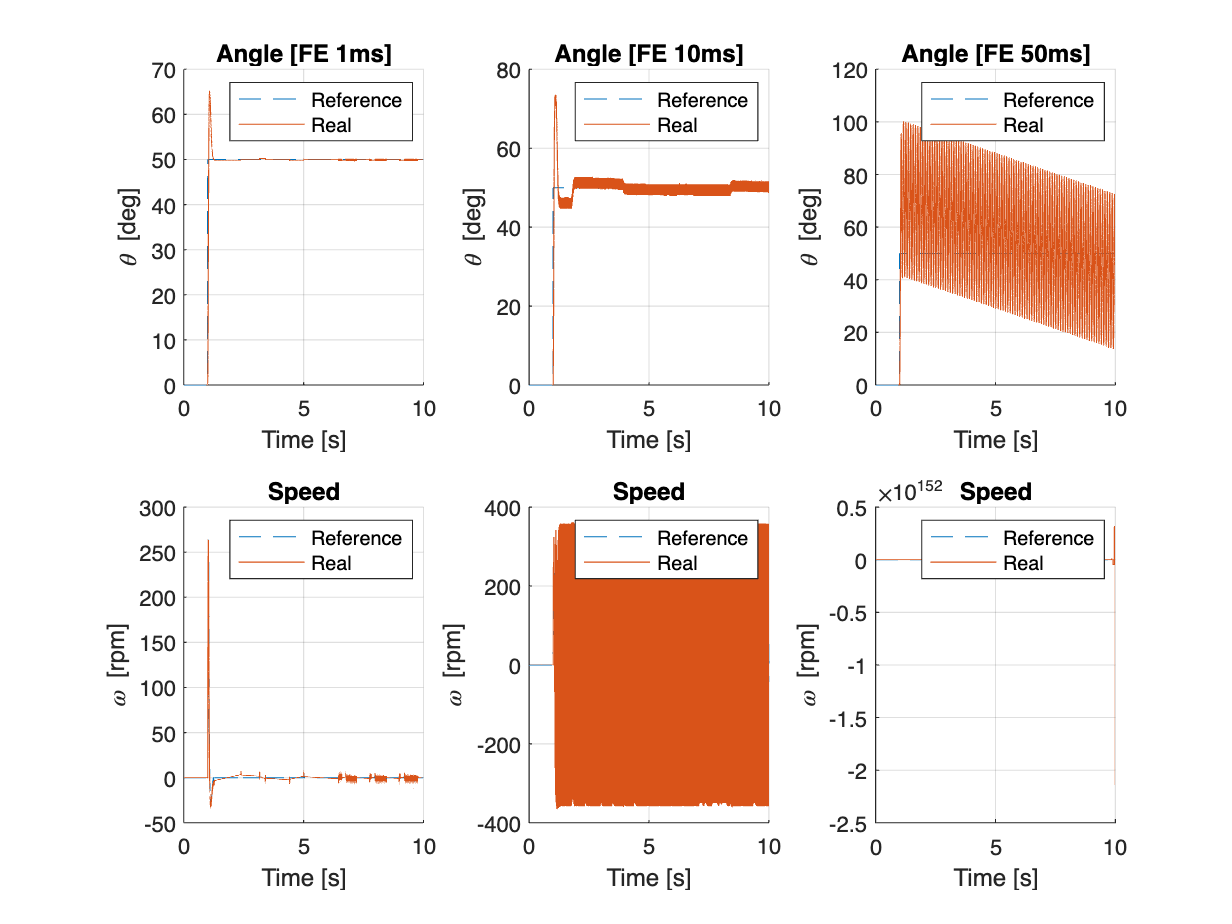

figure
subplot(2,3,1);
hold on;
plot(robust_track.FE.T1.thref.time, robust_track.FE.T1.thref.signals.values,'--');
plot(robust_track.FE.T1.thl_meas.time, robust_track.FE.T1.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [FE 1ms]')

subplot(2,3,2);
hold on;
plot(robust_track.FE.T2.thref.time, robust_track.FE.T2.thref.signals.values,'--');
plot(robust_track.FE.T2.thl_meas.time, robust_track.FE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [FE 10ms]')

subplot(2,3,3);
hold on;
plot(robust_track.FE.T3.thref.time, robust_track.FE.T3.thref.signals.values,'--');
plot(robust_track.FE.T3.thl_meas.time, robust_track.FE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [FE 50ms]')
subplot(2,3,4)
hold on;
plot(robust_track.FE.T1.wl_meas.time, robust_track.FE.T1.wl_meas.signals.values,'--');
plot(robust_track.FE.T1.wl_est.time, robust_track.FE.T1.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(robust_track.FE.T2.wl_meas.time, robust_track.FE.T2.wl_meas.signals.values,'--');
plot(robust_track.FE.T2.wl_est.time, robust_track.FE.T2.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(robust_track.FE.T3.wl_meas.time, robust_track.FE.T3.wl_meas.signals.values,'--');
plot(robust_track.FE.T3.wl_est.time, robust_track.FE.T3.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

Pay attention to the integration method for the additional integrator: it should be 'INTEGRATION FE' according to assingment, but in the simulation we use 'INTGRATION BE' becuase it generally works better. 

**Backward Euler discretization**

simul.Ts_selector = 1;
redObs.Ph0 = inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.Gamma0 = (1 - redObs.A0*T(simul.Ts_selector))\redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0/(1 - redObs.A0*T(simul.Ts_selector));
redObs.J0 = redObs.D0 + redObs.C0/(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);
display(redObs.J0)

         0    1.0000
    0.1360  107.8530



robust_track.BE.T1 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

simul.Ts_selector = 2;
redObs.Ph0 = inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.Gamma0 = (1 - redObs.A0*T(simul.Ts_selector))\redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0/(1 - redObs.A0*T(simul.Ts_selector));
redObs.J0 = redObs.D0 + redObs.C0/(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);
display(redObs.J0)

         0    1.0000
    0.6145   48.7285



robust_track.BE.T2 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

simul.Ts_selector = 3;
redObs.Ph0 = inv(1 - redObs.A0*T(simul.Ts_selector));
redObs.Gamma0 = (1 - redObs.A0*T(simul.Ts_selector))\redObs.B0*T(simul.Ts_selector);
redObs.H0 = redObs.C0/(1 - redObs.A0*T(simul.Ts_selector));
redObs.J0 = redObs.D0 + redObs.C0/(1 - redObs.A0*T(simul.Ts_selector))*redObs.B0*T(simul.Ts_selector);
display(redObs.J0)

         0    1.0000
    0.8941   14.1800



% Using BE in the integrator makes the response bounded (where as with FE it explodes)
robust_track.BE.T3 = sim('ss_robust_estimator_FE','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
% robust_track.BE.T3 = sim('ss_robust_estimator_ADV','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

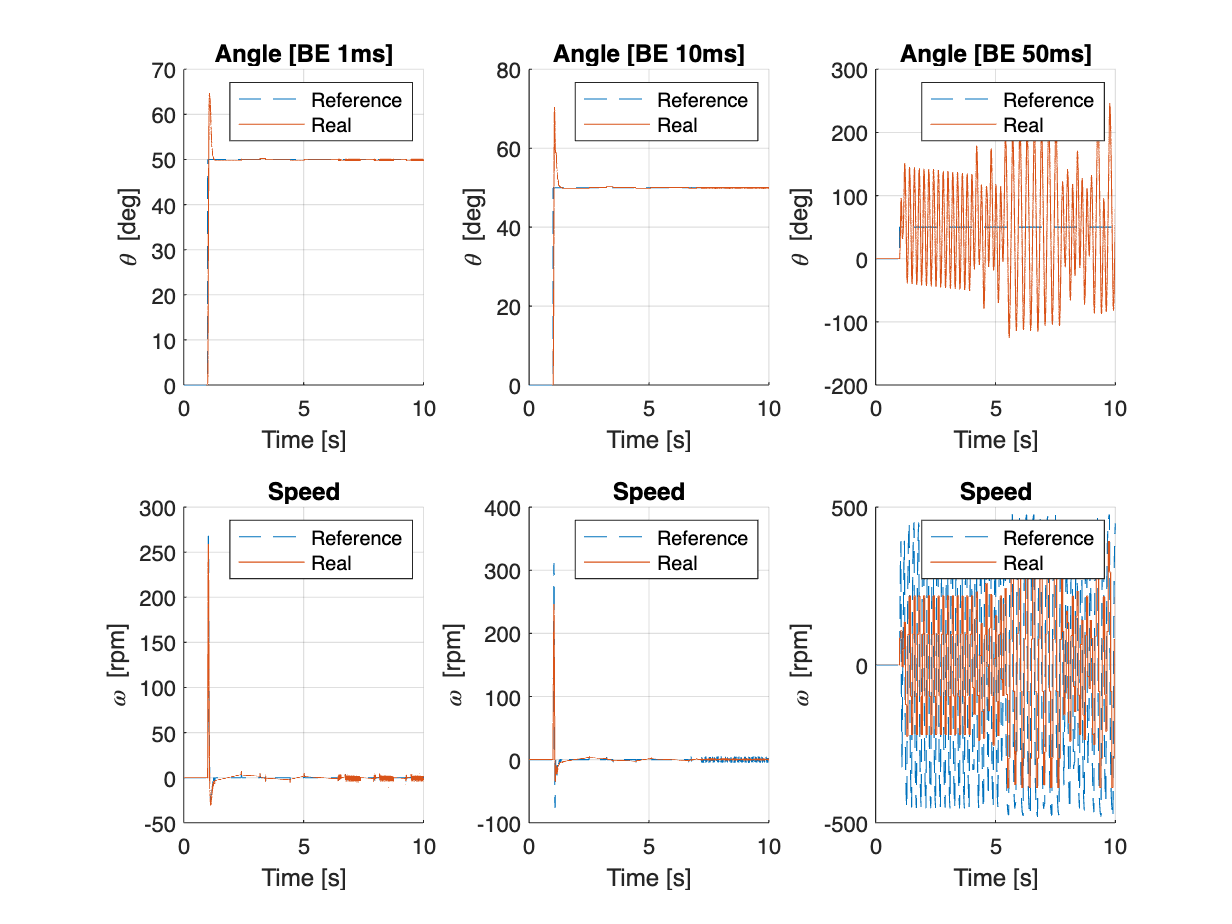

figure
subplot(2,3,1);
hold on;
plot(robust_track.BE.T1.thref.time, robust_track.BE.T1.thref.signals.values,'--');
plot(robust_track.BE.T1.thl_meas.time, robust_track.BE.T1.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [BE 1ms]')

subplot(2,3,2);
hold on;
plot(robust_track.BE.T2.thref.time, robust_track.BE.T2.thref.signals.values,'--');
plot(robust_track.BE.T2.thl_meas.time, robust_track.BE.T2.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [BE 10ms]')

subplot(2,3,3);
hold on;
plot(robust_track.BE.T3.thref.time, robust_track.BE.T3.thref.signals.values,'--');
plot(robust_track.BE.T3.thl_meas.time, robust_track.BE.T3.thl_meas.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [BE 50ms]')
subplot(2,3,4)
hold on;
plot(robust_track.BE.T1.wl_meas.time, robust_track.BE.T1.wl_meas.signals.values,'--');
plot(robust_track.BE.T1.wl_est.time, robust_track.BE.T1.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(robust_track.BE.T2.wl_meas.time, robust_track.BE.T2.wl_meas.signals.values,'--');
plot(robust_track.BE.T2.wl_est.time, robust_track.BE.T2.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(robust_track.BE.T3.wl_meas.time, robust_track.BE.T3.wl_meas.signals.values,'--');
plot(robust_track.BE.T3.wl_est.time, robust_track.BE.T3.wl_est.signals.values);
legend('Reference', 'Real')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

Depending on the integration method we use, 50ms simulation may be bounded (BE) or not (FE)

**Tustin discretization**

We observe that the first column of matrix D has nonzero entries, and this causes an algbraic loop.

simul.Ts_selector = 1;
ssRedObsCT = ss(redObs.A0, redObs.B0, redObs.C0, redObs.D0);
ssRedObsTU= c2d(ssRedObsCT,T(simul.Ts_selector),'tu');
display(ssRedObsTU);

ssRedObsTU =
 
  A = 
          x1
   x1  0.829
 
  B = 
           u1      u2
   x1  0.1438  -26.65
 
  C = 
           x1
   y1       0
   y2  0.9145
 
  D = 
            u1       u2
   y1        0        1
   y2  0.07189    142.5
 
Sample time: 0.001 seconds
Discrete-time state-space model.



## **2.2 **Direct digital desing

The direct design in the discrete–time domain can be performed with any of the available classical or modern design methods, after having obtained a discrete–time model of the plant to be controlled with the exact discretization method.

#### Discretization of the model

Discretise the continuous–time state–space model Σ = (A, B, C, D) of the DC gearmotor using the exact method, to obtain the “ZOH discrete equivalent” Σd = (Φ, Γ, H, J). Note that since D = 0, then also J = 0. This condition will be considered throughout all this section.The discretization can be performed by using the c2d routine of the Control System Toolbox (CST), making sure to specify ’zoh’ as the discretization method.

% define continous time ssm
ssNominalDT.SysCT = ss(ssP.A,ssP.B,ssP.C,ssP.D); 
%reference remains constant during the simulations
simul.stepdeg = 50;

#### **Nominal Tracking**

Design a discrete–time position state–space controller for nominal perfect tracking of constant position set–points, using the discretised plant model Σd obtained in point 1.Since the motor speed is not directly measurable, consider to design a discrete–time reduced– order observer for estimating it. The speed estimate, together with the motor position provided by the encoder, will be used to perform the state feedback.

Simulation for 1 ms

the discrete time state space must be modified for each sample time

simul.Ts_selector = 1;
% creating discrete ssm
ssNominalDT.SysD = c2d(ssNominalDT.SysCT,T(simul.Ts_selector),'zoh');
display(ssNominalDT.SysD); % D must be 0

ans =
 
  A = 
              x1         x2
   x1          1  0.0009846
   x2          0     0.9693
 
  B = 
             u1
   x1  7.78e-05
   x2    0.1548
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



% discrete time observer
%ssNominalDT.redObs.L = 10; % was used before
ssNominalDT.redObs.pole = exp(5*(-2*perf.sigmamin)*T(simul.Ts_selector)); % used in robust, check (5 times faster than minumimal performance, not controller poles)
ssNominalDT.redObs.L = place(ssNominalDT.SysD.A(2,2),ssNominalDT.SysD.A(1,2),ssNominalDT.redObs.pole);
ssNominalDT.redObs.Ph0 = ssNominalDT.SysD.A(2,2) - ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,2);
ssNominalDT.redObs.Gamma0 = [ssNominalDT.SysD.B(2)-ssNominalDT.redObs.L*ssNominalDT.SysD.B(1), ssNominalDT.redObs.Ph0*ssNominalDT.redObs.L+ssNominalDT.SysD.A(2,1)-ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,1)];
ssNominalDT.redObs.C0 = [0; 1];
ssNominalDT.redObs.D0 = [0 1; 0 ssNominalDT.redObs.L];

% CHECK ALL THIS PART
% Nominal tracking gains
ssNominalDT.N = [ssNominalDT.SysD.A-eye(2), ssNominalDT.SysD.B; ssNominalDT.SysD.C, ssNominalDT.SysD.D]\[zeros(2,1); 1];
ssNominalDT.Nx = ssNominalDT.N(1:2); % was ssNominal.N(1:2) before
ssNominalDT.Nu = ssNominalDT.N(3);   % was ssNominal.N(3) before

ssNominal. f = [-perf.d*perf.wn+1i*perf.wn*sqrt(1-perf.d^2), -perf.d*perf.wn-1i*perf.wn*sqrt(1-perf.d^2)];
% old poles --> must be transformed
ssNominalDT.poles = exp(ssNominal.poles*T(simul.Ts_selector));
ssNominalDT.K = place(ssNominalDT.SysD.A, ssNominalDT.SysD.B, ssNominalDT.poles);

ss_direct_nominal.T1 = sim('ss_nominal_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_nominal.T1.ssNominalDT = ssNominalDT;

Simulation for 10 ms

simul.Ts_selector = 2;
% creating discrete ssm
ssNominalDT.SysD = c2d(ssNominalDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
%ssNominalDT.redObs.L = 10; % Why 10?
ssNominalDT.redObs.pole = exp(5*(-2*perf.sigmamin)*T(simul.Ts_selector));
ssNominalDT.redObs.L = place(ssNominalDT.SysD.A(2,2),ssNominalDT.SysD.A(1,2),ssNominalDT.redObs.pole);
ssNominalDT.redObs.Ph0 = ssNominalDT.SysD.A(2,2) - ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,2);
ssNominalDT.redObs.Gamma0 = [ssNominalDT.SysD.B(2)-ssNominalDT.redObs.L*ssNominalDT.SysD.B(1), ssNominalDT.redObs.Ph0*ssNominalDT.redObs.L+ssNominalDT.SysD.A(2,1)-ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,1)];
ssNominalDT.redObs.C0 = [0; 1];
ssNominalDT.redObs.D0 = [0 1; 0 ssNominalDT.redObs.L];

ssNominalDT.N = [ssNominalDT.SysD.A - eye(2), ssNominalDT.SysD.B; ssNominalDT.SysD.C ssNominalDT.SysD.D]\[zeros(2,1); 1];
ssNominalDT.Nx = ssNominalDT.N(1:2);
ssNominalDT.Nu = ssNominalDT.N(3);
%ssNominal.poles = [-10+5*1i, -10-5*1i];
ssNominal.poles = [-perf.d*perf.wn+1i*perf.wn*sqrt(1-perf.d^2), -perf.d*perf.wn-1i*perf.wn*sqrt(1-perf.d^2)];
% old poles --> must be transformed
ssNominalDT.poles = exp(ssNominal.poles*T(simul.Ts_selector));
ssNominalDT.K = place(ssNominalDT.SysD.A, ssNominalDT.SysD.B, ssNominalDT.poles);

ss_direct_nominal.T2 = sim('ss_nominal_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_nominal.T2.ssNominalDT = ssNominalDT;

Simulation for 50 ms

simul.Ts_selector = 3;
% creating discrete ssm
ssNominalDT.SysD = c2d(ssNominalDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
%ssNominalDT.redObs.L = 10;
ssNominalDT.redObs.pole = exp(5*(-2*perf.sigmamin)*T(simul.Ts_selector));
ssNominalDT.redObs.L = place(ssNominalDT.SysD.A(2,2),ssNominalDT.SysD.A(1,2),ssNominalDT.redObs.pole);
ssNominalDT.redObs.Ph0 = ssNominalDT.SysD.A(2,2) - ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,2);
ssNominalDT.redObs.Gamma0 = [ssNominalDT.SysD.B(2)-ssNominalDT.redObs.L*ssNominalDT.SysD.B(1), ssNominalDT.redObs.Ph0*ssNominalDT.redObs.L+ssNominalDT.SysD.A(2,1)-ssNominalDT.redObs.L*ssNominalDT.SysD.A(1,1)];
ssNominalDT.redObs.C0 = [0; 1];
ssNominalDT.redObs.D0 = [0 1; 0 ssNominalDT.redObs.L];

% CHECK ALL THIS PART
ssNominalDT.N = [ssNominalDT.SysD.A - eye(2), ssNominalDT.SysD.B; ssNominalDT.SysD.C ssNominalDT.SysD.D]\[zeros(2,1); 1];
ssNominalDT.Nx = ssNominalDT.N(1:2);
ssNominalDT.Nu = ssNominalDT.N(3);

ssNominal.poles = [-perf.d*perf.wn+1i*perf.wn*sqrt(1-perf.d^2), -perf.d*perf.wn-1i*perf.wn*sqrt(1-perf.d^2)];
% old poles --> must be transformed
ssNominalDT.poles = exp(ssNominal.poles*T(simul.Ts_selector));
ssNominalDT.K = place(ssNominalDT.SysD.A, ssNominalDT.SysD.B, ssNominalDT.poles);

ss_direct_nominal.T3 = sim('ss_nominal_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_nominal.T3.ssNominalDT = ssNominalDT;

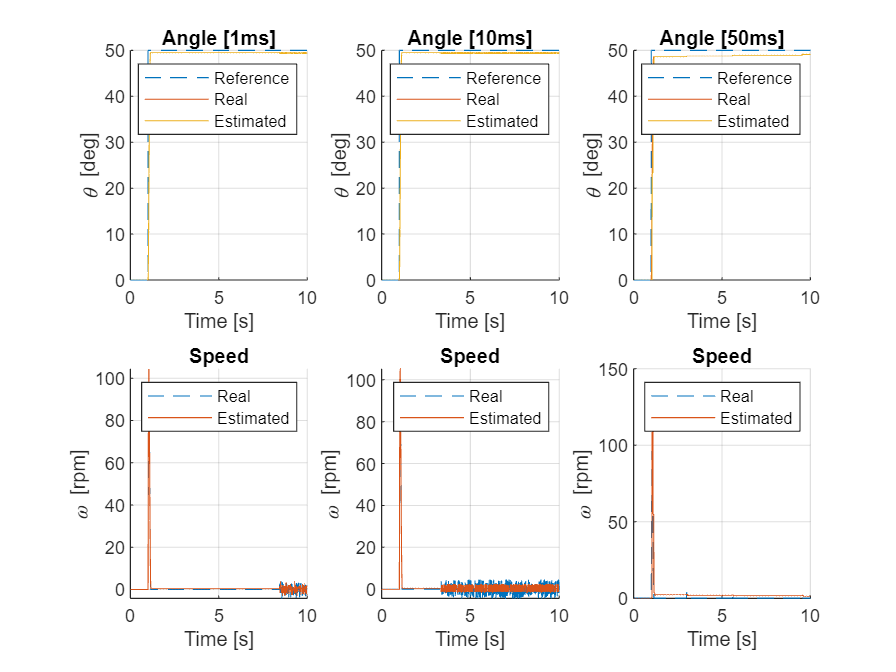

figure
subplot(2,3,1);
hold on;
plot(ss_direct_nominal.T1.thref.time, ss_direct_nominal.T1.thref.signals.values,'--');
plot(ss_direct_nominal.T1.thl_meas.time, ss_direct_nominal.T1.thl_meas.signals.values);
plot(ss_direct_nominal.T1.thl_est.time, ss_direct_nominal.T1.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [1ms]')

subplot(2,3,2);
hold on;
plot(ss_direct_nominal.T2.thref.time, ss_direct_nominal.T2.thref.signals.values,'--');
plot(ss_direct_nominal.T2.thl_meas.time, ss_direct_nominal.T2.thl_meas.signals.values);
plot(ss_direct_nominal.T2.thl_est.time, ss_direct_nominal.T2.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [10ms]')

subplot(2,3,3);
hold on;
plot(ss_direct_nominal.T3.thref.time, ss_direct_nominal.T3.thref.signals.values,'--');
plot(ss_direct_nominal.T3.thl_meas.time, ss_direct_nominal.T3.thl_meas.signals.values);
plot(ss_direct_nominal.T3.thl_est.time, ss_direct_nominal.T3.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [50ms]')
subplot(2,3,4)
hold on;
plot(ss_direct_nominal.T1.wl_meas.time, ss_direct_nominal.T1.wl_meas.signals.values,'--');
plot(ss_direct_nominal.T1.wl_est.time, ss_direct_nominal.T1.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;
plot(ss_direct_nominal.T2.wl_meas.time, ss_direct_nominal.T2.wl_meas.signals.values,'--');
plot(ss_direct_nominal.T2.wl_est.time, ss_direct_nominal.T2.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(ss_direct_nominal.T3.wl_meas.time, ss_direct_nominal.T3.wl_meas.signals.values,'--');
plot(ss_direct_nominal.T3.wl_est.time, ss_direct_nominal.T3.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

Direct design also works for 50ms, while emulation fails.

#### **Robust perfect tracking**

Design a discrete–time position state–space controller with integral action to achieve robust perfect tracking of constant position set–points, and perfect rejection of constant turbances. For the design, use the discretised plant model Σd obtained in point discrete–time reduced–order observer similar to that obtained in point 2.

Integrator set to 'ACCUMULATION FE'

% define continous time ssm
ssRobustDT.SysCT = ss(ssP.A,ssP.B,ssP.C,ssP.D); 
%reference remains constant during the simulations
simul.stepdeg = 50;

Simulation for 1 ms

the discrete time state space must be modified for each sample time

simul.Ts_selector = 1;
% creating discrete ssm
ssRobustDT.SysD = c2d(ssRobustDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer

ssRobustDT.N = [ssRobustDT.SysD.A - eye(2) ssRobustDT.SysD.B; ssRobustDT.SysD.C ssRobustDT.SysD.D]\[zeros(2,1); 1];
ssRobustDT.Nx = ssRobustDT.N(1:2);
ssRobustDT.Nu = ssRobustDT.N(3);

ssRobustDT.Phe = [1 ssRobustDT.SysD.C ;zeros(2, 1) ssRobustDT.SysD.A];
ssRobustDT.Gammae =[0; ssRobustDT.SysD.B];

ssRobust.poles = [-2*perf.sigmamin + 1i*perf.wdmax, -2*perf.sigmamin - 1i*perf.wdmax, -2*perf.sigmamin];
% old poles --> must be transformed
ssRobustDT.poles = exp(ssRobust.poles*T(simul.Ts_selector));

ssRobustDT.Ke = place(ssRobustDT.Phe, ssRobustDT.Gammae, ssRobustDT.poles);
ssRobustDT.K = ssRobustDT.Ke(2:3);
ssRobustDT.Ki = ssRobustDT.Ke(1);

ssRobustDT.redObs.pole = exp(5*(-2*perf.sigmamin)*T(simul.Ts_selector));
%ssRobustDT.redObs.L = ssRobustDT.SysD.A(2,2)/ssRobustDT.SysD.A(1,2);
ssRobustDT.redObs.L = place(ssRobustDT.SysD.A(2,2),ssRobustDT.SysD.A(1,2),ssRobustDT.redObs.pole); % works because L is a scalar
ssRobustDT.redObs.Ph0 = ssRobustDT.SysD.A(2,2) - ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,2);
ssRobustDT.redObs.Gamma0 = [ssRobustDT.SysD.B(2)-ssRobustDT.redObs.L*ssRobustDT.SysD.B(1) ssRobustDT.redObs.Ph0*ssRobustDT.redObs.L+ssRobustDT.SysD.A(2,1)-ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,1)];
ssRobustDT.redObs.C0 = [0; 1];
ssRobustDT.redObs.D0 = [0 1; 0 ssRobustDT.redObs.L];

ss_direct_robust.T1 = sim('ss_robust_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_robust.T1.ssRobustDT = ssRobustDT;

Simulation for 10 ms

simul.Ts_selector = 2;
% creating discrete ssm
ssRobustDT.SysD = c2d(ssRobustDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
ssRobustDT.N = [ssRobustDT.SysD.A - eye(2) ssRobustDT.SysD.B; ssRobustDT.SysD.C ssRobustDT.SysD.D]\[zeros(2,1); 1];
ssRobustDT.Nx = ssRobustDT.N(1:2);
ssRobustDT.Nu = ssRobustDT.N(3);

ssRobustDT.Phe = [1 ssRobustDT.SysD.C ;zeros(2, 1) ssRobustDT.SysD.A];
ssRobustDT.Gammae =[0; ssRobustDT.SysD.B];

ssRobust.poles = [-2*perf.sigmamin + 1i*perf.wdmax, -2*perf.sigmamin - 1i*perf.wdmax, -2*perf.sigmamin];
% old poles --> must be transformed
ssRobustDT.poles = exp(ssRobust.poles*T(simul.Ts_selector));

ssRobustDT.Ke = place(ssRobustDT.Phe, ssRobustDT.Gammae, ssRobustDT.poles);
ssRobustDT.K = ssRobustDT.Ke(2:3);
ssRobustDT.Ki = ssRobustDT.Ke(1);

ssRobustDT.redObs.pole = exp(5*(-2*perf.sigmamin)*T(simul.Ts_selector));
ssRobustDT.redObs.L = place(ssRobustDT.SysD.A(2,2),ssRobustDT.SysD.A(1,2),ssRobustDT.redObs.pole);
ssRobustDT.redObs.Ph0 = ssRobustDT.SysD.A(2,2) - ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,2);
ssRobustDT.redObs.Gamma0 = [ssRobustDT.SysD.B(2)-ssRobustDT.redObs.L*ssRobustDT.SysD.B(1) ssRobustDT.redObs.Ph0*ssRobustDT.redObs.L+ssRobustDT.SysD.A(2,1)-ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,1)];
ssRobustDT.redObs.C0 = [0; 1];
ssRobustDT.redObs.D0 = [0 1; 0 ssRobustDT.redObs.L];

ss_direct_robust.T2 = sim('ss_robust_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_robust.T2.ssRobustDT = ssRobustDT;

Simulation for 50 ms

simul.Ts_selector = 3;
% creating discrete ssm
ssRobustDT.SysD = c2d(ssRobustDT.SysCT,T(simul.Ts_selector),'zoh');
% discrete time observer
ssRobustDT.N = [ssRobustDT.SysD.A - eye(2) ssRobustDT.SysD.B; ssRobustDT.SysD.C ssRobustDT.SysD.D]\[zeros(2,1); 1];
ssRobustDT.Nx = ssRobustDT.N(1:2);
ssRobustDT.Nu = ssRobustDT.N(3);

ssRobustDT.Phe = [1 ssRobustDT.SysD.C ;zeros(2, 1) ssRobustDT.SysD.A];
ssRobustDT.Gammae =[0; ssRobustDT.SysD.B];

ssRobust.poles = [-2*perf.sigmamin + 1i*perf.wdmax, -2*perf.sigmamin - 1i*perf.wdmax, -2*perf.sigmamin];
% old poles --> must be transformed
ssRobustDT.poles = exp(ssRobust.poles*T(simul.Ts_selector));

ssRobustDT.Ke = place(ssRobustDT.Phe, ssRobustDT.Gammae, ssRobustDT.poles);
ssRobustDT.K = ssRobustDT.Ke(2:3);
ssRobustDT.Ki = ssRobustDT.Ke(1);

ssRobustDT.redObs.pole = exp(5*(-2*perf.sigmamin)*T(simul.Ts_selector));
ssRobustDT.redObs.L = place(ssRobustDT.SysD.A(2,2),ssRobustDT.SysD.A(1,2),ssRobustDT.redObs.pole);
ssRobustDT.redObs.Ph0 = ssRobustDT.SysD.A(2,2) - ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,2);
ssRobustDT.redObs.Gamma0 = [ssRobustDT.SysD.B(2)-ssRobustDT.redObs.L*ssRobustDT.SysD.B(1) ssRobustDT.redObs.Ph0*ssRobustDT.redObs.L+ssRobustDT.SysD.A(2,1)-ssRobustDT.redObs.L*ssRobustDT.SysD.A(1,1)];
ssRobustDT.redObs.C0 = [0; 1];
ssRobustDT.redObs.D0 = [0 1; 0 ssRobustDT.redObs.L];
ss_direct_robust.T3 = sim('ss_robust_direct','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
ss_direct_robust.T3.ssRobustDT = ssRobustDT;

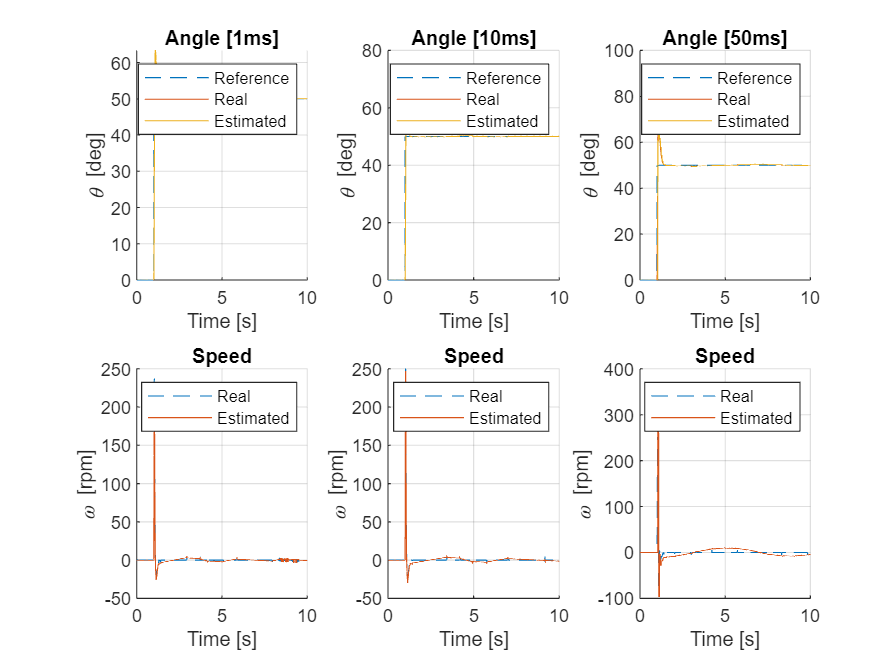

figure
subplot(2,3,1);
hold on;
plot(ss_direct_robust.T1.thref.time, ss_direct_robust.T1.thref.signals.values,'--');
plot(ss_direct_robust.T1.thl_meas.time, ss_direct_robust.T1.thl_meas.signals.values);
plot(ss_direct_robust.T1.thl_est.time, ss_direct_robust.T1.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [1ms]')

subplot(2,3,2);
hold on;
plot(ss_direct_robust.T2.thref.time, ss_direct_robust.T2.thref.signals.values,'--');
plot(ss_direct_robust.T2.thl_meas.time, ss_direct_robust.T2.thl_meas.signals.values);
plot(ss_direct_robust.T2.thl_est.time, ss_direct_robust.T2.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [10ms]')

subplot(2,3,3);
hold on;
plot(ss_direct_robust.T3.thref.time, ss_direct_robust.T3.thref.signals.values,'--');
plot(ss_direct_robust.T3.thl_meas.time, ss_direct_robust.T3.thl_meas.signals.values);
plot(ss_direct_robust.T3.thl_est.time, ss_direct_robust.T3.thl_est.signals.values);
legend('Reference', 'Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle [50ms]')

subplot(2,3,4)
hold on;
plot(ss_direct_robust.T1.wl_meas.time, ss_direct_robust.T1.wl_meas.signals.values,'--');
plot(ss_direct_robust.T1.wl_est.time, ss_direct_robust.T1.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,5)
hold on;

plot(ss_direct_robust.T2.wl_meas.time, ss_direct_robust.T2.wl_meas.signals.values,'--');
plot(ss_direct_robust.T2.wl_est.time, ss_direct_robust.T2.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,3,6)
hold on;
plot(ss_direct_robust.T3.wl_meas.time, ss_direct_robust.T3.wl_meas.signals.values,'--');
plot(ss_direct_robust.T3.wl_est.time, ss_direct_robust.T3.wl_est.signals.values);
legend('Real', 'Estimated')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')

## **CHALLENGE**

asymptotoc step reference

overshoot<10% for 60deg step

settling time <= 0.2s

longest possible sampling time

In the table there are the reference values from last year winning group

$\left\lbrack \begin{array}{ccc}
\textrm{Sampling}\;\textrm{time} & \textrm{Ts} & 0\ldotp 2\\
\textrm{Rise}\;\textrm{time} & t_r  & 0\ldotp 15\\
\textrm{Settling}\;\textrm{time} & t_{s,5%}  & 0\ldotp 2\\
\textrm{Overshoot} & M_p  & 4\ldotp 79
\end{array}\right\rbrack$ pid values $\left\lbrack \begin{array}{ccc}
K_i  &  & 1\ldotp 67\\
K_p  &  & 0\ldotp 6\\
K_d  &  & 0\ldotp 0885\\
T_l  &  & 0\ldotp 0069
\end{array}\right\rbrack$  kp= 0.605 everything works even after sampling

simul.stepdeg = 60;
challenge.Ts = 0.202;
challenge.pid.voltage = 1.4012;
challenge.pid.Ki = 1.5;
challenge.pid.Kp = 0.5;
challenge.pid.Tl =  1/(2*perf.wg);
%challenge.pid.Tl = 0.0069;

challenge.simul = sim('challenge_simul','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

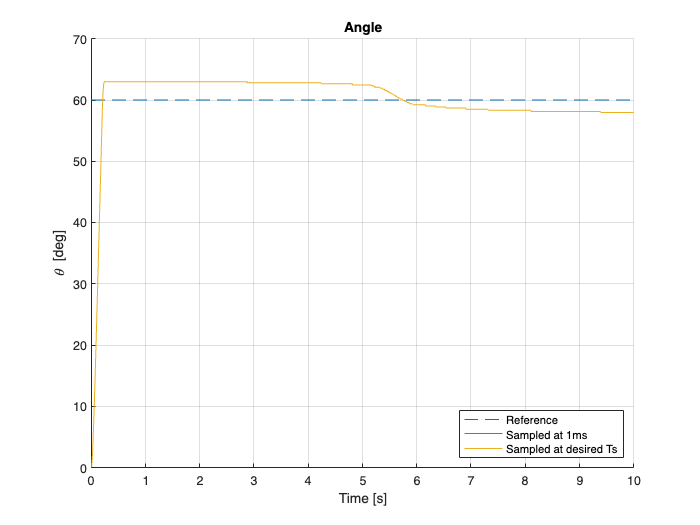

figure();
hold on;
plot(challenge.simul.thref.time, challenge.simul.thref.signals.values,'--');
plot(challenge.simul.thl_meas.time, challenge.simul.thl_meas.signals.values);
plot(challenge.simul.thl_sample.time, challenge.simul.thl_sample.signals.values);
legend('Reference', 'Sampled at 1ms', 'Sampled at desired Ts','Location', 'southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')

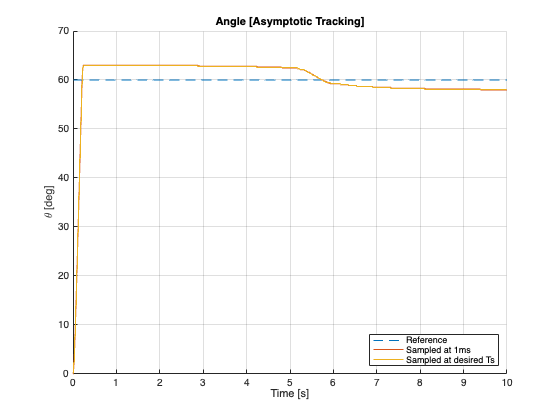

figure();
hold on;
plot(challenge.simul.thref.time, challenge.simul.thref.signals.values,'--');
plot(challenge.simul.thl_meas.time, challenge.simul.thl_meas.signals.values);
stairs(challenge.simul.thl_sample.time, challenge.simul.thl_sample.signals.values);
legend('Reference', 'Sampled at 1ms', 'Sampled at desired Ts', 'Location', 'southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')

title('Angle [Asymptotic Tracking]')

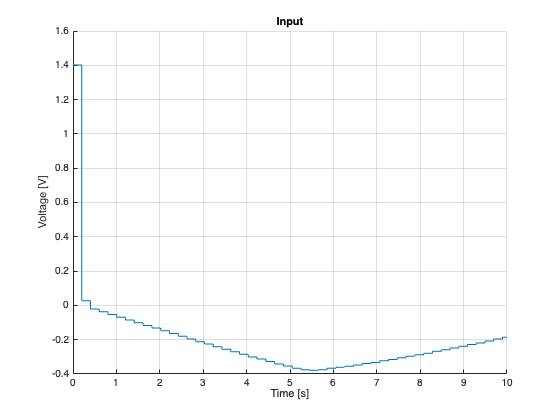


figure();
hold on;
plot(challenge.simul.u.time, challenge.simul.u.signals.values);
grid on;
xlabel('Time [s]')
ylabel('Voltage [V]')
title('Input')

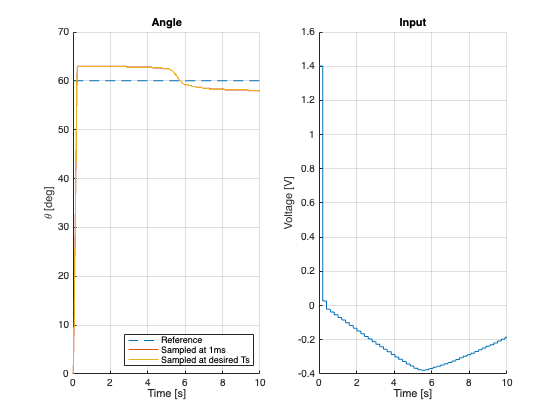

figure()
subplot(1,2,1)
hold on;
plot(challenge.simul.thref.time, challenge.simul.thref.signals.values,'--');
plot(challenge.simul.thl_meas.time, challenge.simul.thl_meas.signals.values);
stairs(challenge.simul.thl_sample.time, challenge.simul.thl_sample.signals.values);
legend('Reference', 'Sampled at 1ms', 'Sampled at desired Ts','Location', 'southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
xlim([0 10])
title('Angle')

subplot(1,2,2)
hold on;
plot(challenge.simul.u.time, challenge.simul.u.signals.values);
grid on;
xlabel('Time [s]')
ylabel('Voltage [V]')
title('Input')
xlim([0 10])

information on the step with signal with Ts 0.001 

stepinfo(challenge.simul.thl_meas.signals.values,challenge.simul.thref.time,simul.stepdeg, 'SettlingTimeThreshold', 0.05, 'RiseTimeLimits', [0.0, 0.95])

ans = struct with fields:
         RiseTime: 0.1963
    TransientTime: 0.2003
     SettlingTime: 0.2003
      SettlingMin: 57.2400
      SettlingMax: 63
        Overshoot: 5.0000
       Undershoot: 0
             Peak: 63
         PeakTime: 0.2370


information on the step with signal with maximum Ts

%stepinfo(challenge.simul.thl_sample.signals.values,challenge.simul.thref.time,simul.stepdeg, 'SettlingTimeThreshold', 0.05, 'RiseTimeLimits', [0.001, 0.95])